Tämä skripti sisältää kandidaatintyöhön sisältyvän testauksen. Siinä on useita osioita, ja ne ovat siinä järjestyksessä, miten testit ovat edenneet.

Init

 
% Poista kaikki entiset muuttujat, ikkunat ja komentohistoria
clc
clear all
close all

% Lisää alihakemistot
mainfolder = getPath;
addpath(genpath(strcat(mainfolder,'\Algorithms')));
addpath(genpath(strcat(mainfolder,'\Tools')));
addpath(genpath(strcat(mainfolder,'\ignore')));
addpath(genpath(strcat(mainfolder,'\data')));

Tallenna data

 
choose = "saved"

choose = "saved"


if choose == "sensor"
    % tallenna anturista
    time = 60;
    topic = "velodyne_points";
    IP_address = "127.0.0.1";
    pcSet = saveRosData(time, topic, IP_address);

elseif choose == "saved"
    % Vaihtoehtoisesti käytetään tallennettua dataa.
    % Tallenna datapaketti osoitteesta:


[https://tuni-my.sharepoint.com/:f:/g/personal/markus_hautala_tuni_fi/EqMrzbfX0W1BkObC2WGypbwBZJshim-_KwTy8prTLD4_nw?e=M3OFuB](https://tuni-my.sharepoint.com/:f:/g/personal/markus_hautala_tuni_fi/EqMrzbfX0W1BkObC2WGypbwBZJshim-_KwTy8prTLD4_nw?e=M3OFuB)

    %load("savedData.mat")
    load("savedData_final.mat")

end

Esikäsittelytestaus yksittäiselle pistepilvelle

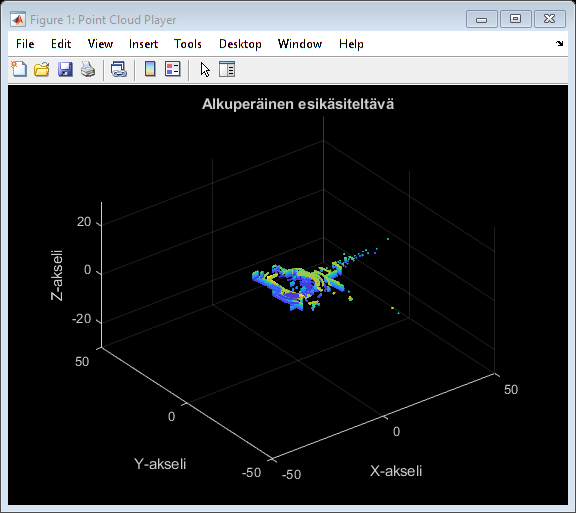

 
show1 = showPc('Alkuperäinen esikäsiteltävä', pc);

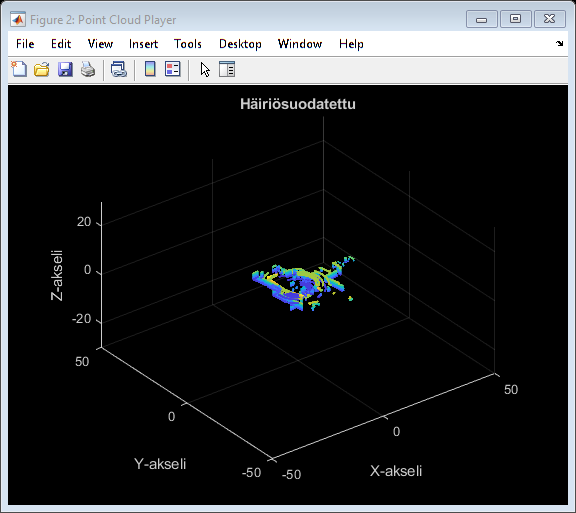


%% Häiriösuodatus
pc_denoised = pcdenoise(pc);
show2 = showPc('Häiriösuodatettu', pc_denoised);


% Kuinka paljon pisteitä hävisi:
losed_points = size_of_pc(pc) - size_of_pc(pc_denoised)

losed_points = 35



%% Alinäytteistys
laatikon_koko = 0.1; % (m)
tic
pc_downsampled_grid = pcdownsample(pc, 'gridAverage', laatikon_koko);
time_of_grid = toc

time_of_grid = 0.0577

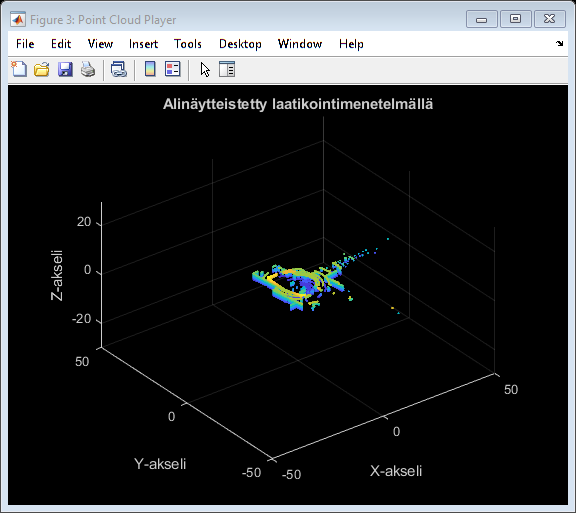

show3 = showPc('Alinäytteistetty laatikointimenetelmällä', pc_downsampled_grid);


% Prosentuaalinen pistepilven koko verrattuna ennen alinäytteistystä:
pros_koko = size_of_pc(pc_downsampled_grid) / size_of_pc(pc)

pros_koko = 0.3844


% Verrataan satunnaismenetelmään:
tic
pc_downsampled_rand = pcdownsample(pc, "random", pros_koko);
time_of_random = toc

time_of_random = 0.0342

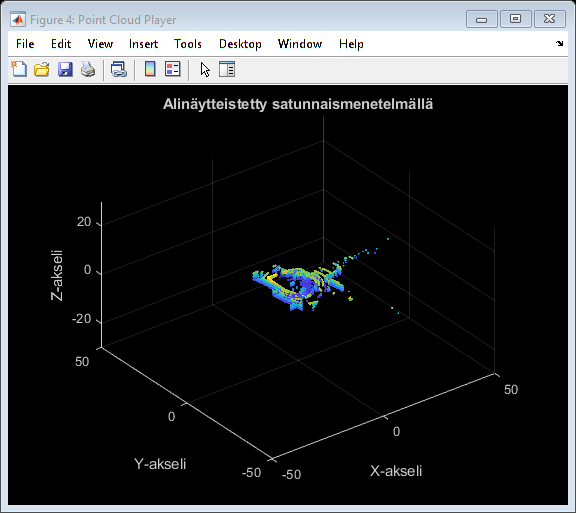

show4 = showPc('Alinäytteistetty satunnaismenetelmällä', pc_downsampled_rand);

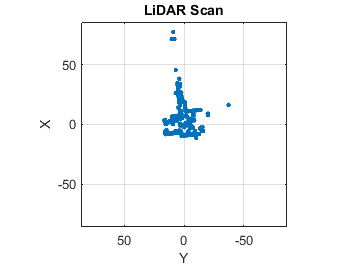



% 3D to 2D
lidarScan_limited = pc2laser({pc}, -0.5, 1.5);
figure
plot(lidarScan_limited{1});

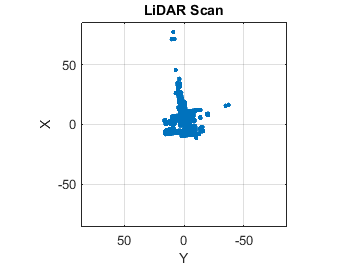


lidarScan_unlimited = pc2laser({pc}, -50, 50);
figure
plot(lidarScan_unlimited{1});

Esikäsittely SLAM algoritmeille

 
eachFrame = 2;
preprocessedpcSet = preprocess(pcSet, eachFrame);
lidarSet = pc2laser(preprocessedpcSet, -0.5, 1.5);
size_of_psSet(preprocessedpcSet)

ans = 323

Reaalikartta

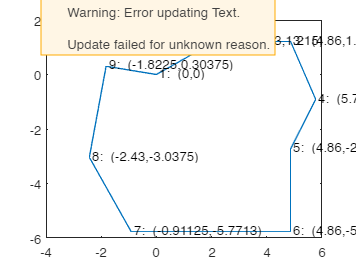

figure
x = groundTruth(:,1);
y = groundTruth(:,2);
plot(x, y)
for t = 1:9
  text(x(t)+0.1,y(t)+0.1,[num2str(t), ':  (', num2str(x(t)), ',', num2str(y(t)), ')'])
end

SLAM algoritmit

 
disp('Navigation Toolbox')

Navigation Toolbox


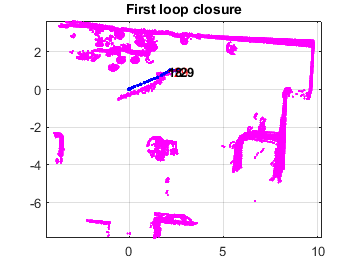

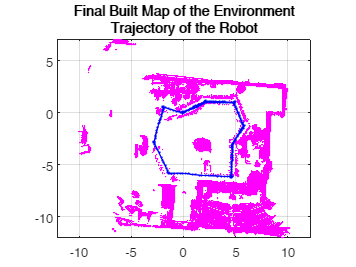

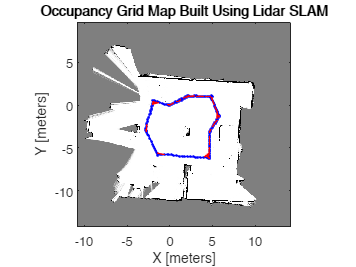

optimizedPoses =          0         0         0
   -0.0078    0.0199    0.2136
    0.0245    0.0485    0.2068
    0.0849    0.0507    0.2066
    0.1752    0.1033    0.2271
    0.2892    0.1609    0.2283
    0.4785    0.2211    0.2354
    0.6219    0.2805    0.2469
    0.8371    0.3573    0.2751
    0.9839    0.4286    0.2861


tic
optimizedPoses = navigationTB_example(lidarSet)

navigationTB_time = toc;
[routelengths_navi, distances_navi] = getResults(optimizedPoses, groundTruth, eachFrame);

 
disp('Computer vision toolbox')

Computer vision toolbox


Error using matlab.internal.editor.figure.WarningGraphicsIcon/setupTextBox
Error while evaluating HTMLCanvas ErrorCallback.

Error using matlab.internal.editor.figure.WarningGraphicsIcon/setupTextBox
Error while evaluating HTMLCanvas ErrorCallback.

Error using matlab.internal.editor.figure.WarningGraphicsIcon/setupTextBox
Error while evaluating HTMLCanvas ErrorCallback.

Error using matlab.internal.editor.figure.WarningGraphicsIcon/setupTextBox
Error while evaluating HTMLCanvas ErrorCallback.

Error using matlab.internal.editor.figure.WarningGraphicsIcon/setupTextBox
Error while evaluating HTMLCanvas ErrorCallback.

Error using matlab.internal.editor.figure.WarningGraphicsIcon/setupTextBox
Error while evaluating HTMLCanvas ErrorCallback.

Error using matlab.internal.editor.figure.WarningGraphicsIcon/setupTextBox
Error while evaluating HTMLCanvas ErrorCallback.

Error using matlab.internal.editor.figure.WarningGraphicsIcon/setupTextBox
Error while evaluating HTMLCanvas ErrorCallback.



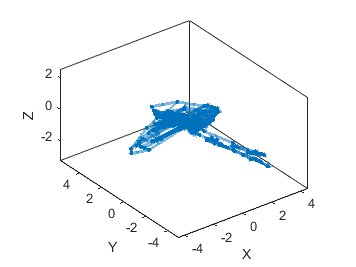

tic
computerVisionTB_example1

computerVisionTB1_time = toc;
[routelengths_vision, distances_vision] = getResults(pcViewSet2vect(vSet), groundTruth, eachFrame);

 
tic
%computerVisionTB_example2
computerVisionTB2_time = toc;

 
disp('Lidar toolbox')

Lidar toolbox


scans = 1×323 cell array
    {1×1 lidarScan}    {1×1 lidarScan}    {1×1 lidarScan}    {1×1 lidarScan}    {1×1 lidarScan}    {1×1 lidarScan}    {1×1 lidarScan}    {1×1 lidarScan}    {1×1 lidarScan}    {1×1 lidarScan}    {1×1 lidarScan}    {1×1 lidarScan}    {1×1 lidarScan}    {1×1 lidarScan}    {1×1 lidarScan}    {1×1 lidarScan}    {1×1 lidarScan}    {1×1 lidarScan}    {1×1 lidarScan}    {1×1 lidarScan}    {1×1 lidarScan}    {1×1 lidarScan}    {1×1 lidarScan}    {1×1 lidarScan}    {1×1 lidarScan}    {1×1 lidarScan}    {1×1 lidarScan}    {1×1 lidarScan}    {1×1 lidarScan}    {1×1 lidarScan}    {1×1 lidarScan}    {1×1 lidarScan}    {1×1 lidarScan}    {1×1 lidarScan}    {1×1 lidarScan}    {1×1 lidarScan}    {1×1 lidarScan}    {1×1 lidarScan}    {1×1 lidarScan}    {1×1 lidarScan}    {1×1 lidarScan}    {1×1 lidarScan}    {1×1 lidarScan}    {1×1 lidarScan}    {1×1 lidarScan}    {1×1 lidarScan}    {1×1 lidarScan}    {1×1 lidarScan}    {1×1 lidarScan}    {1×1 lidarScan}    {1×1 lidarScan}    {1

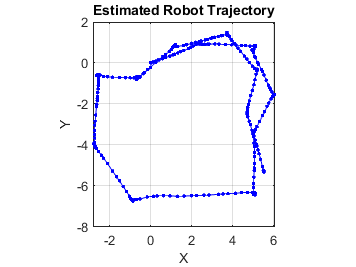

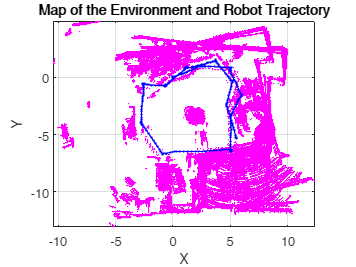

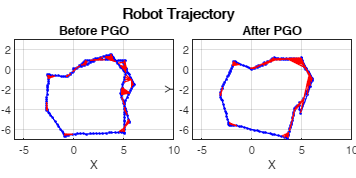

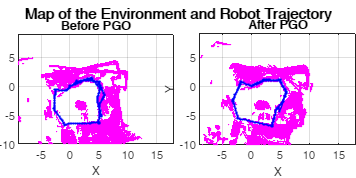

tic
lidarTB_example

lidarTB_time = toc;
[routelengths_lidar, distances_lidar] = getResults(updatedPGraph.nodeEstimates, groundTruth, eachFrame);

calculateResults

routelengths_keskiarvo = 1×3 single row vector
    0.2056    4.4341    0.4989


distances_keskiarvo = 1×3 single row vector
    0.2831    5.0297    0.7012


final_tulos = 1×3 single row vector
   40.3395  876.2789  136.5311


orig_data = preprocessedpcSet;

Esikäsittelytestausten testaus parhaammalla SLAM algoritmilla = navigation TB

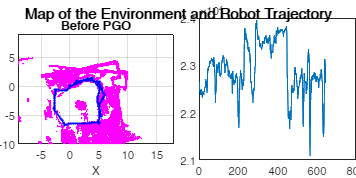

[points_in_pc_mean, lengths_original_pcSet] = mean_points_in_pc(pcSet);
plot(lengths_original_pcSet)

Alinäytteistys vs näytteenottotaajuus

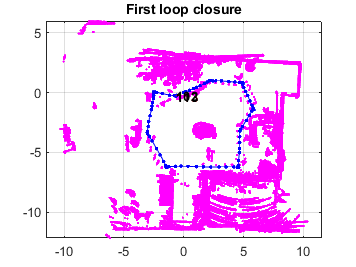

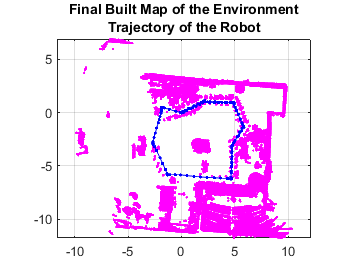

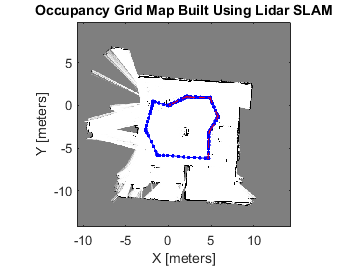

downsampleVSsamplerate1 =   SLAMprocess with properties:

                  eachFrame: 4
           performPcDenoise: 0
           downsamplemethod: 'random'
    downsampleToPointAmount: 8000
                        fov: 60
                    zLimits: [-0.5000 1.5000]
                      pcSet: {1×646 cell}
         pcSet_preprocessed: {1×162 cell}
                   lidarSet: {1×162 cell}
                groundTruth: [15×3 double]
             optimizedPoses: [162×3 double]
            time_preprocess: 37.2380
                  time_SLAM: 713.6916
               results_time: [2×1 double]
               routeLengths: [15×1 double]
                  distances: [15×1 double]
                results_map: [15×2 double]


downsampleVSsamplerate1 = SLAMprocess(pcSet, groundTruth);
downsampleVSsamplerate1.eachFrame = 4*1;
downsampleVSsamplerate1.performPcDenoise = false;
downsampleVSsamplerate1.downsamplemethod = 'random';
downsampleVSsamplerate1.downsampleToPointAmount = 4*2000;
downsampleVSsamplerate1 = downsampleVSsamplerate1.runAll

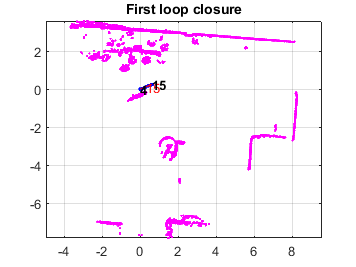

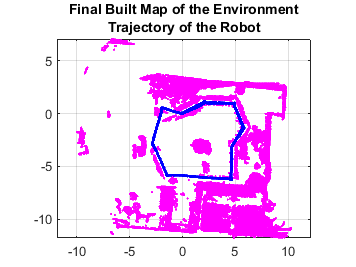

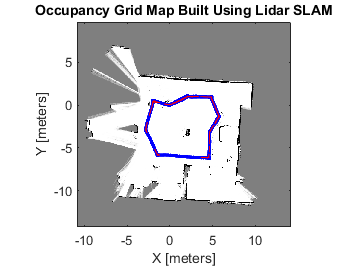

downsampleVSsamplerate2 =   SLAMprocess with properties:

                  eachFrame: 1
           performPcDenoise: 0
           downsamplemethod: 'random'
    downsampleToPointAmount: 2000
                        fov: 60
                    zLimits: [-0.5000 1.5000]
                      pcSet: {1×646 cell}
         pcSet_preprocessed: {1×646 cell}
                   lidarSet: {1×646 cell}
                groundTruth: [15×3 double]
             optimizedPoses: [646×3 double]
            time_preprocess: 355.8175
                  time_SLAM: 904.4187
               results_time: [2×1 double]
               routeLengths: [15×1 double]
                  distances: [15×1 double]
                results_map: [15×2 double]



downsampleVSsamplerate2 = SLAMprocess(pcSet, groundTruth);
downsampleVSsamplerate2.eachFrame = 1*1;
downsampleVSsamplerate2.performPcDenoise = false;
downsampleVSsamplerate2.downsamplemethod = 'random';
downsampleVSsamplerate2.downsampleToPointAmount = 1*2000;
downsampleVSsamplerate2 = downsampleVSsamplerate2.runAll


downsampleVSsamplerate2_results_map = [downsampleVSsamplerate1.results_map downsampleVSsamplerate2.results_map];
downsampleVSsamplerate2_results_mtime = [downsampleVSsamplerate1.results_time downsampleVSsamplerate2.results_time];

Häiriösuodatuksen vaikutus

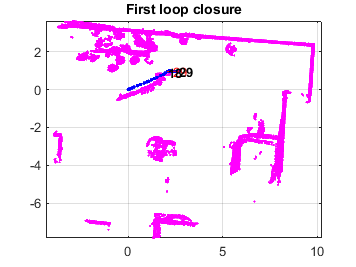

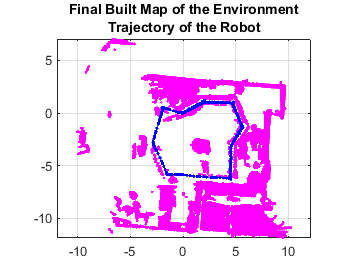

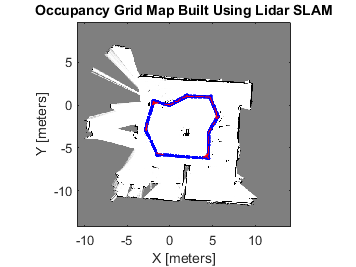

pcdenoise_results1 =   SLAMprocess with properties:

                  eachFrame: 2
           performPcDenoise: 1
           downsamplemethod: 'random'
    downsampleToPointAmount: 10000
                        fov: 60
                    zLimits: [-0.5000 1.5000]
                      pcSet: {1×646 cell}
         pcSet_preprocessed: {1×323 cell}
                   lidarSet: {1×323 cell}
                groundTruth: [15×3 double]
             optimizedPoses: [323×3 double]
            time_preprocess: 114.0608
                  time_SLAM: 1.9268e+03
               results_time: [2×1 double]
               routeLengths: [15×1 double]
                  distances: [15×1 double]
                results_map: [15×2 double]


pcdenoise_results1 = SLAMprocess(pcSet, groundTruth);
pcdenoise_results1.eachFrame = 2;
pcdenoise_results1.performPcDenoise = true;
pcdenoise_results1.downsamplemethod = 'random';
pcdenoise_results1.downsampleToPointAmount = 10000;
pcdenoise_results1 = pcdenoise_results1.runAll

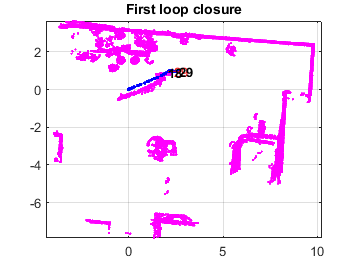

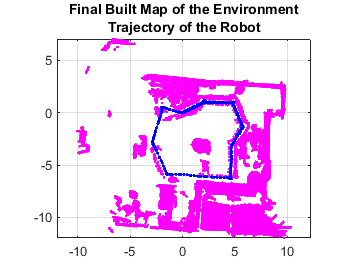

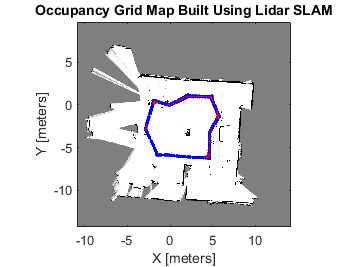

pcdenoise_results2 =   SLAMprocess with properties:

                  eachFrame: 2
           performPcDenoise: 0
           downsamplemethod: 'random'
    downsampleToPointAmount: 10000
                        fov: 60
                    zLimits: [-0.5000 1.5000]
                      pcSet: {1×646 cell}
         pcSet_preprocessed: {1×323 cell}
                   lidarSet: {1×323 cell}
                groundTruth: [15×3 double]
             optimizedPoses: [323×3 double]
            time_preprocess: 83.9686
                  time_SLAM: 1.9090e+03
               results_time: [2×1 double]
               routeLengths: [15×1 double]
                  distances: [15×1 double]
                results_map: [15×2 double]



pcdenoise_results2 = SLAMprocess(pcSet, groundTruth);
pcdenoise_results2.eachFrame = 2;
pcdenoise_results2.performPcDenoise = false;
pcdenoise_results2.downsamplemethod = 'random';
pcdenoise_results2.downsampleToPointAmount = 10000;
pcdenoise_results2 = pcdenoise_results2.runAll


pcdenoise_results_map = [pcdenoise_results1.results_map pcdenoise_results2.results_map];
pcdenoise_results_mtime = [pcdenoise_results1.results_time pcdenoise_results2.results_time];

Alinäytteistysmenetelmät

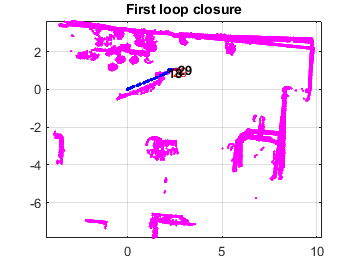

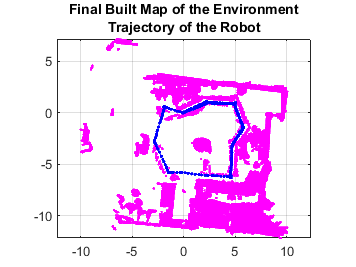

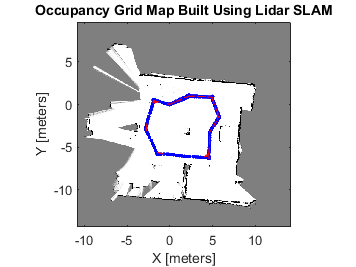

gridvsrandom_results1 =   SLAMprocess with properties:

                  eachFrame: 2
           performPcDenoise: 1
           downsamplemethod: 'gridAverage'
    downsampleToPointAmount: 0.1000
                        fov: 60
                    zLimits: [-0.5000 1.5000]
                      pcSet: {1×646 cell}
         pcSet_preprocessed: {1×323 cell}
                   lidarSet: {1×323 cell}
                groundTruth: [15×3 double]
             optimizedPoses: [323×3 double]
            time_preprocess: 89.7594
                  time_SLAM: 686.7171
               results_time: [2×1 double]
               routeLengths: [15×1 double]
                  distances: [15×1 double]
                results_map: [15×2 double]


gridvsrandom_results1 = SLAMprocess(pcSet, groundTruth);
gridvsrandom_results1.eachFrame = 2;
gridvsrandom_results1.downsamplemethod = 'gridAverage';
gridvsrandom_results1.downsampleToPointAmount = 0.1;
gridvsrandom_results1 = gridvsrandom_results1.runAll

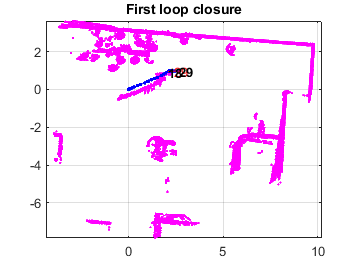

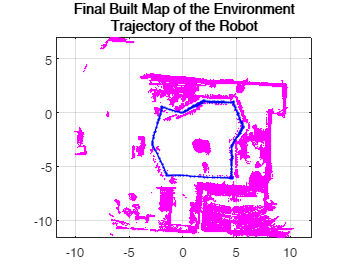

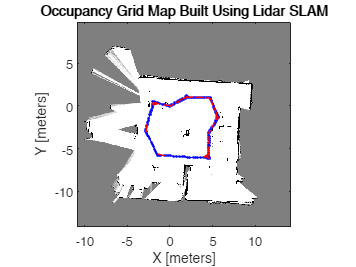

gridvsrandom_results2 =   SLAMprocess with properties:

                  eachFrame: 2
           performPcDenoise: 1
           downsamplemethod: 'random'
    downsampleToPointAmount: 6.5516e+03
                        fov: 60
                    zLimits: [-0.5000 1.5000]
                      pcSet: {1×646 cell}
         pcSet_preprocessed: {1×323 cell}
                   lidarSet: {1×323 cell}
                groundTruth: [15×3 double]
             optimizedPoses: [323×3 double]
            time_preprocess: 88.4905
                  time_SLAM: 1.2563e+03
               results_time: [2×1 double]
               routeLengths: [15×1 double]
                  distances: [15×1 double]
                results_map: [15×2 double]



gridvsrandom_results2 = SLAMprocess(pcSet, groundTruth);
gridvsrandom_results2.eachFrame = 2;
gridvsrandom_results2.downsamplemethod = 'random';
gridvsrandom_results2.downsampleToPointAmount = mean_points_in_pc(gridvsrandom_results1.pcSet_preprocessed);
gridvsrandom_results2 = gridvsrandom_results2.runAll


gridvsrandom_results_map = [gridvsrandom_results1.results_map gridvsrandom_results2.results_map];
gridvsrandom_results_mtime = [gridvsrandom_results1.results_time gridvsrandom_results2.results_time];